# Pràctica 7. Exercici 7

Exercici 3 del document CN_full5.pdf

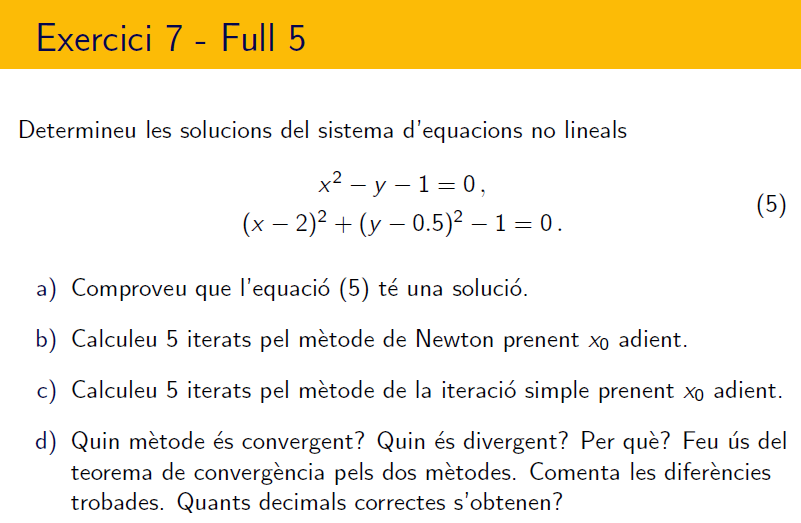

================================================================================

- `Comproveu que el sistema d'equacions té almenys una solució`

f1 = @(x,y)x^2-y-1;
f2 = @(x,y)(x-2)^2 + (y-0.5)^2 - 1;
fimplicit(f1,[-3 4 -2 3],':r','LineWidth',2)

hold on
fimplicit(f2,[-3 4 -2 3],'--g','LineWidth',2),grid

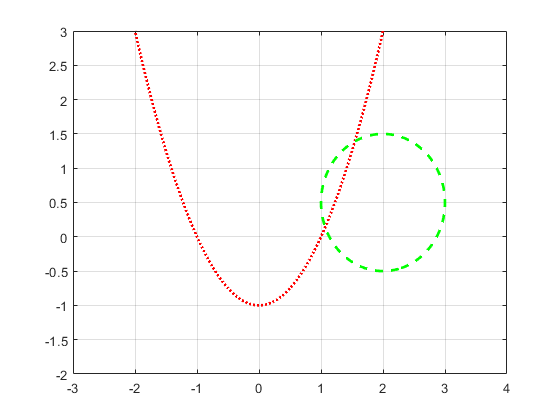

hold off

- `Calculeu 5 iterats pel mètode de Newton, prenent x0 adient`

% TODO

- `Calculeu 5 iterats pel mètode de l'iteració simple, prenent x0 adient`

% TODO
G1 = @(x,y)sqrt(y+1);
G2 = @(x,y)((x-2)^2+y^2+0.5^2-1)/(2*0.5);
t = [0, 1]';
for k=1:5
    t(1)=G1(t(1),t(2));
    t(2)=G2(t(1),t(2));
    disp([k,t'])
end

            1       1.4142      0.59315

            2       1.2622      0.14617

            3       1.0706      0.13516

            4       1.0654      0.14167

            5       1.0685      0.13778



- `Compareu els resultats obtinguts amb el resultat de fsolve de MATLAB®. Quants decimals correctes s'obtenen? `

options = optimset('Display','iter'); % show iterations
x0 = [2, 1.5]; [x, fval] = fsolve(@myfun,x0,options)


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3            2.25                             6               1
     1          6       0.0395508          0.375          0.352               1
     2          9     0.000252571       0.122283         0.0216               1
     3         12     2.21289e-08       0.012091       0.000233               1
     4         15     1.60229e-16    0.000111923       2.05e-08               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<<a href = "ma

x =        1.5463       1.3912


fval =    1.7974e-09    1.253e-08


x0 = [0, 1]; [x, fval] = fsolve(@myfun,x0,options)


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3         14.5625                            13               1
     1          6         1.45284              1           3.45               1
     2          9       0.0840647        0.49766          0.433             2.5
     3         12      0.00125667       0.188277         0.0662             2.5
     4         15     3.30127e-07      0.0237829        0.00084             2.5
     5         18     3.60296e-14     0.00043436       3.07e-07             2.5

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 

x =        1.0673      0.13923


fval =    2.0905e-08   1.8866e-07


function F = myfun(x) 
    F(1) = x(1)^2-x(2)-1; 
    F(2) = (x(1)-2)^2 + (x(2)-0.5)^2 - 1;
end